clc;
clear;
cfgNonHT = wlanNonHTConfig(PSDULength=61);

rfRxFreq = 2.437e9;

rx = comm.SDRuReceiver( ...
    'Platform',         'B210', ...
    'SerialNum',        '344C4DE', ...
    'MasterClockRate', 20e6, ...
    'CenterFrequency',  rfRxFreq,...
    'Gain', 30,...
    'OutputDataType', 'double');

[rxData, ~] = capture(rx, 5, 'Seconds');

detect the packet

startOffset = wlanPacketDetect(rxData,'CBW10');

Calculate the LLTF index points

idxLLTF = wlanFieldIndices(cfgNonHT, 'L-LTF');

Get non-HT fields

ind = wlanFieldIndices(cfgNonHT);
nonHTFields = rxData(startOffset+(ind.LSTF(1):ind.LSIG(2)),:);

Demodulate the LLTF 

demodSig = wlanLLTFDemodulate(nonHTFields(idxLLTF(1):idxLLTF(2), :), cfgNonHT);

Get channel estimation

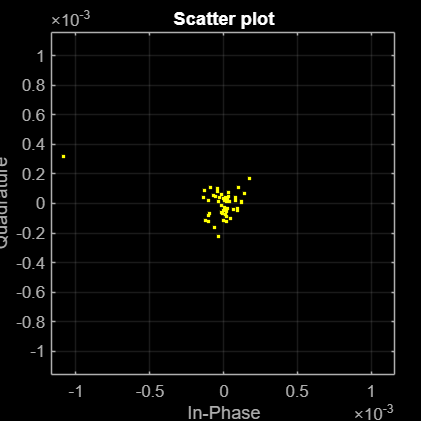

est = wlanLLTFChannelEstimate(demodSig, cfgNonHT);
scatterplot(est);
grid;